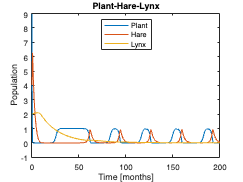

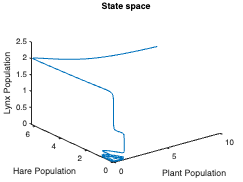

%Scenario 1: The system exhibits stable oscillations with a periodicity of approximately 70 months.

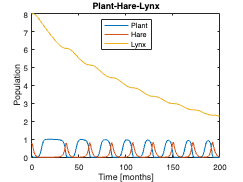


t0 = 0;                 	
tfinal = 200;                
y0= [0.1 0.8 8];               
tspan = [t0 tfinal];        
a1= 5;              
a2= 0.1;           
b1= 3;               
b2= 10;                                     
d1= 0.4;            
d2= 0.01;           

%Each point on the population of the 3 species models vs. time (in months) is calculated using the
% provided function called "plants_hare_lynx_"
[t,y] = ode23(@(t,y) plants_hare_lynx_(t,y,a1,a2,b1,b2,d1,d2), tspan, y0);

% plotting the population over time
figure("Name",'hare-lynx');
plot(t,y)
title('Plant-Hare-Lynx');
xlabel('Time [months]');
ylabel('Population');
legend('Plant','Hare','Lynx','Location','North')

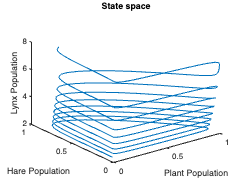

figure("Name",'State space')
plot3(y(:,1),y(:,2),y(:,3))
title('State space')
xlabel('Plant Population')
ylabel('Hare Population')
zlabel('Lynx Population')

As we can see, this model shows a stable oscillation period of about 40-50 months. As the population of hare increases, the lynxes have more food to survive and reproduce. When reaching the highest saturation point, the lynxes put more pressure on hare reproduction, leading to their decrease. Their decrease results in a following increase in plant mass growth. 